# **Final Project**

## Embedded Signal Processing System - ENE4069

### Fall semester, 2023

### Prof. Keonwook Kim

After solve following problems, submit the below files and documentations. Turn in yours to eclass by due date.

- **MATLAB file** for problem 1

- Individual STM32CubeIDE **project file **for problem 2

- **PDF Report** to explain your approches and logics

Problem 1. You are asked to recover two music audios in MATLAB.

Below program shows how to make two music channel signal from individual audio. Load final project file and hear some sound as below. 

load finalProjectData.mat
%soundsc(out1,fs)
%soundsc(out2,fs)

You can hear each music from out1 and out2 data. We combine the music together by filtering and modulating. First, let's make the signal for the bandlimited format as below.

lpf1 = fir1(100,1/4);   % LPF for wc = pi/4 with 101 length
out1_1 = filter(lpf1,1,out1);       % Perform filtering on out1
out2_1 = filter(lpf1,1,out2);       % Perform filtering on out2
modulator = (-1).^(0:1:(length(out1)-1));   % Frequency shift by pi
out2_2 = out2_1.*modulator';               % Frequency shift by pi
out = out1_1+out2_2;    % Final two channel audio
%soundsc(out,fs)

You can hear one music audio; however, it actually has two music inside. The spectrogram shows that one music is located at the low frequency and the other music is place at the high frequency as below. 

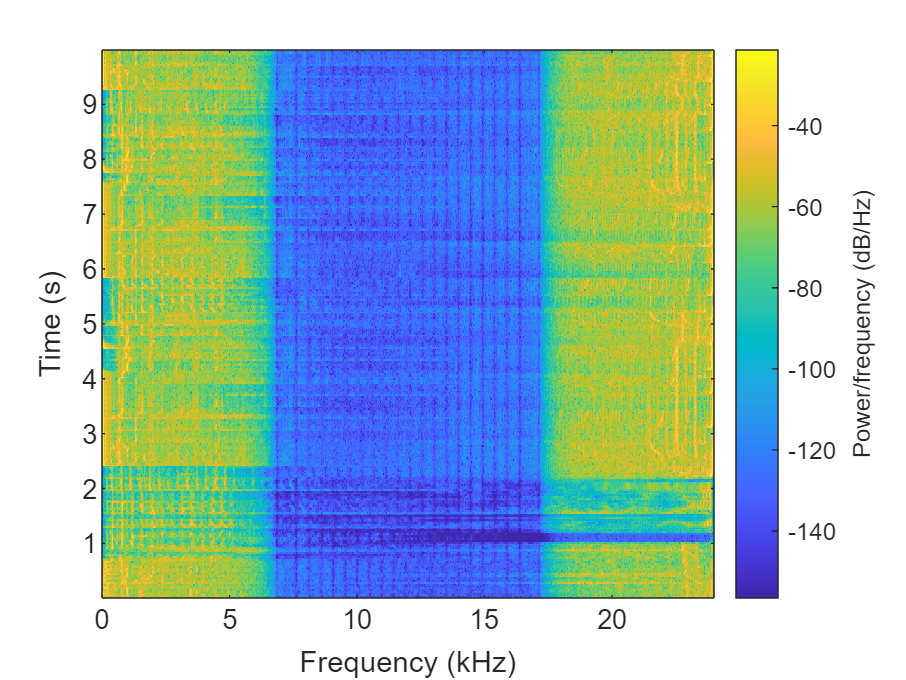

spectrogram(out,hanning(2048),512,[],fs)

From the out data, separate the two music for audible sound in MATLAB.

Problem 2. You are asked to recover two music audios using ARM processor.

Use the Problem 1 method, you are given to perform the audio separation from twoChannelMusic.wav file. Play the wave file using your player and realize the separation in real time based on below configuration. One channel in left audio and the other channel in right audio.